# Question 3

a) Plot a histogram of the times between two consecutive photons

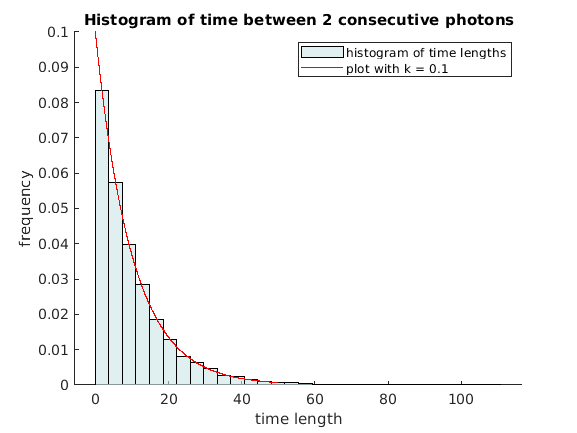

times = load('times.mat');
times = times.times;
lengths = zeros(1, length(times) - 1);

for i=1:length(times) - 1
    lengths(1,i) = times(1,i+1) - times(1,i);
end

figure
hold on;
h = histogram(lengths, 30, 'Normalization', 'pdf');
h.FaceColor = [0.8 0.9 0.9];

k = 0.1;
t = 0:0.01:50;
y = k * exp(-k * t);
plot(t,y, 'r')
title("Histogram of time between 2 consecutive photons")
xlabel('time length')
ylabel('frequency')
legend('histogram of time lengths', 'plot with k = 0.1')
saveas(gcf,'histo.jpg')

b) 

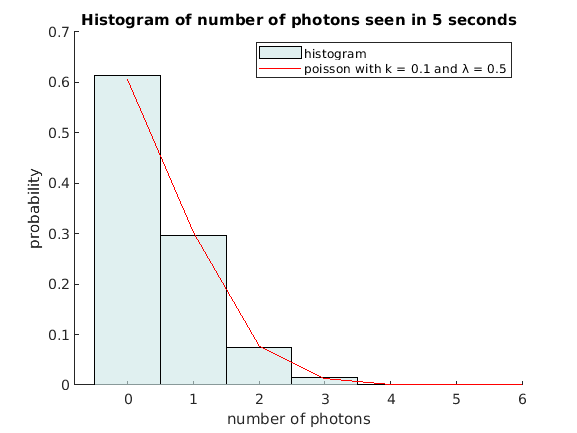

N = 500;
M = 10000;
k = 0.1;
dt = 0.01;

counts = zeros(N,1);
total = 0;
sums = zeros(M, 1);

for i=1:M
    y = zeros(N,1);
    x = rand(N,1);
    y(x<(k*dt)) = 1;
    counts = counts + y;
    total = total + sum(y);
    sums(i, 1) = sum(y);
end

figure
hold on;
h = histogram(sums, "Normalization", "probability");
h.FaceColor = [0.8 0.9 0.9];

l = 0.5;
x = 0:1:6;
y = zeros(1, 7);
for i=1:7
    x1 = x(1, i);
    y(1, i) = ((l ^ x1) / factorial(x1)) * exp(-l);
end
% y = ((l ^ x) / factorial(x)) * exp(-l)
% y
plot(x,y, 'r')
title("Histogram of number of photons seen in 5 seconds")
xlabel("number of photons")
ylabel("probability")
legend('histogram', 'poisson with k = 0.1 and λ = 0.5')
saveas(gcf,'histo2.jpg')